# An Overview of MBSA (Multimodal Brain Signal Analysis) Program for LINK LAB

Written By **Yeonseo Choo **(@Korea University College of Medicine; seanchoo03@korea.ac.kr)

## Data aquisition from INTAN and preprocessing progress

Most electrophysiology data is collected using INTAN ([https://www.intantech.com/](https://www.intantech.com/)). The resulting raw signal files are in **.RHD** format, which must be converted into a readable data format before preprocessing and further analysis. Following process will guide to the usage of **.RHD** files.

function create_file(dir)
    % Ensure the directory exists; if not, create it
    if ~exist(dir, 'dir')
        mkdir(dir);
        disp([dir " doesn't exist. It was automatically created by MBSA"]);
    else
        disp("File already exists.")
    end
end

### 1.0 Parameter initialization & Importing Data

Here, we need to initialize the directory of the output and input data.

addpath('./rawdata');
addpath('./utils');
addpath('./utils/methods')
abs_raw_dir = './rawdata/electrophysiology/eeg';
abs_target_dir = './processed_data/eeg';

name_of_project = "240711_organoid";
number_of_channel = 8;
sampling_frequency = 20000;
raw_data_directory = fullfile(abs_raw_dir, name_of_project);
save_directory = fullfile(abs_target_dir, name_of_project);
create_file(raw_data_directory); % asserting if the file exists.

File already exists.


create_file(save_directory); % asserting if the file exists.

File already exists.


Now let's read and save the intan result by each channel in .mat format.


Reading Intan Technologies RHD2000 Data File, Version 1.5

Found 8 amplifier channels.
Found 3 auxiliary input channels.
Found 1 supply voltage channel.
Found 0 board ADC channels.
Found 0 board digital input channels.
Found 0 board digital output channels.
Found 0 temperature sensor channels.

File contains 233.316 seconds of data.  Amplifiers were sampled at 20.00 kS/s.

Allocating memory for data...
Reading data from file...
10% done...
20% done...
30% done...
40% done...
50% done...
60% done...
70% done...
80% done...
90% done...
100% done...
Parsing data...
No missing timestamps in data.
Applying notch filter...
10% done...
20% done...
30% done...
40% done...
50% done...
60% done...
70% done...
80% done...
Done!  Elapsed time: 1.3 seconds
Extracted data are now available in the MATLAB workspace.
Type 'whos' to see variables.

finish converting
t_start = 15, t_end = 20


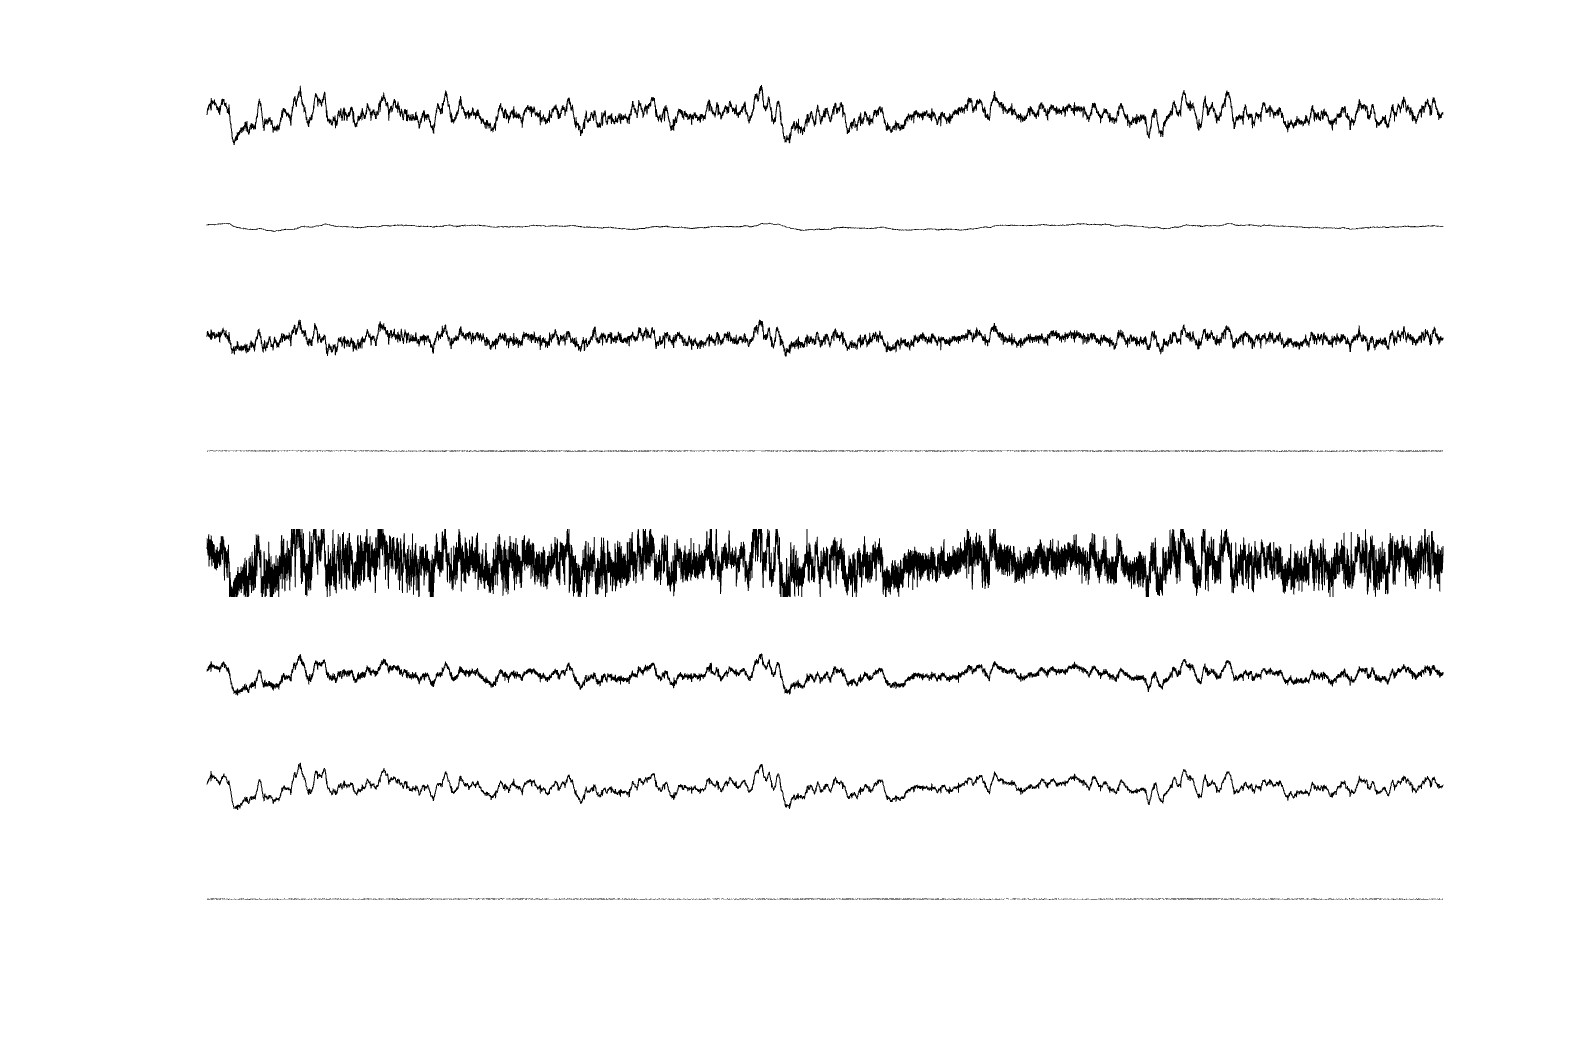

intan_reader(name_of_project, number_of_channel, raw_data_directory, save_directory);

### 1.1 Data Preprocessing - Low Pass Filter

First select the channel numbers for preprocessing.

pch = [1, 2, 3, 4, 5, 6, 7, 8];

Now we preprocess these channel data by user's custom methods. Methods are stored in the utils/method folder.

for i = pch
    chn_dir = fullfile(raw_data_directory, sprintf('E_%d.mat', i));
    resch_dir = fullfile(save_directory, sprintf('E_%d.mat', i));
    disp(chn_dir);
    temp_chn_vals = load(chn_dir).data;
    data = low_pass_filter(temp_chn_vals, sampling_frequency, 100);
    save(resch_dir, 'data');
end

./rawdata/electrophysiology/eeg/240711_organoid/E_1.mat
./rawdata/electrophysiology/eeg/240711_organoid/E_2.mat
./rawdata/electrophysiology/eeg/240711_organoid/E_3.mat
./rawdata/electrophysiology/eeg/240711_organoid/E_4.mat
./rawdata/electrophysiology/eeg/240711_organoid/E_5.mat
./rawdata/electrophysiology/eeg/240711_organoid/E_6.mat
./rawdata/electrophysiology/eeg/240711_organoid/E_7.mat
./rawdata/electrophysiology/eeg/240711_organoid/E_8.mat


t_start = 15, t_end = 20


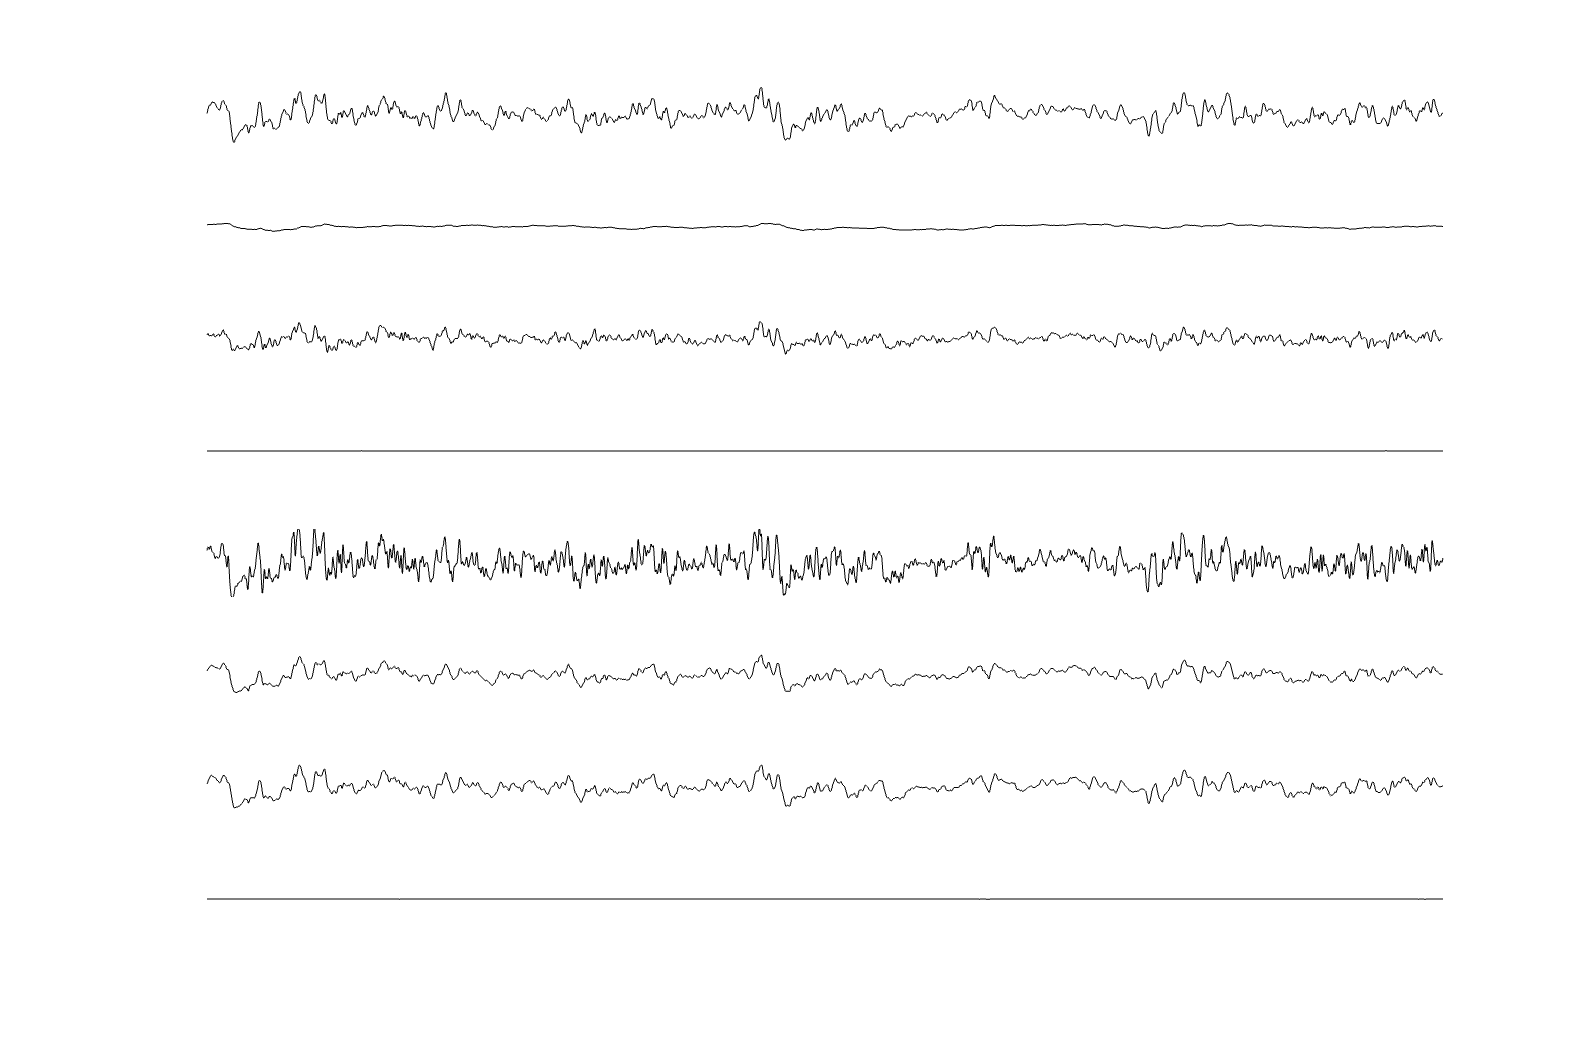

clf;  % Clears the current figure (Do not delete this line of code.)
figure;
strl = repmat({'E_'}, 1, number_of_channel);
chl = num2cell(1:number_of_channel);
save_as_TIF(strl, chl, 'total_img', 1, save_directory);

### 1.2 Data Preprocessing - Average Smoother

pch = [5];
for i = pch
    chn_dir = fullfile(raw_data_directory, sprintf('E_%d.mat', i));
    resch_dir = fullfile(save_directory, sprintf('E_%d.mat', i));
    disp(chn_dir);
    temp_chn_vals = load(chn_dir).data;
    data = average_smoother(temp_chn_vals, 300, 0.1);
    save(resch_dir, 'data');
end

./rawdata/electrophysiology/eeg/240711_organoid/E_5.mat


t_start = 15, t_end = 20


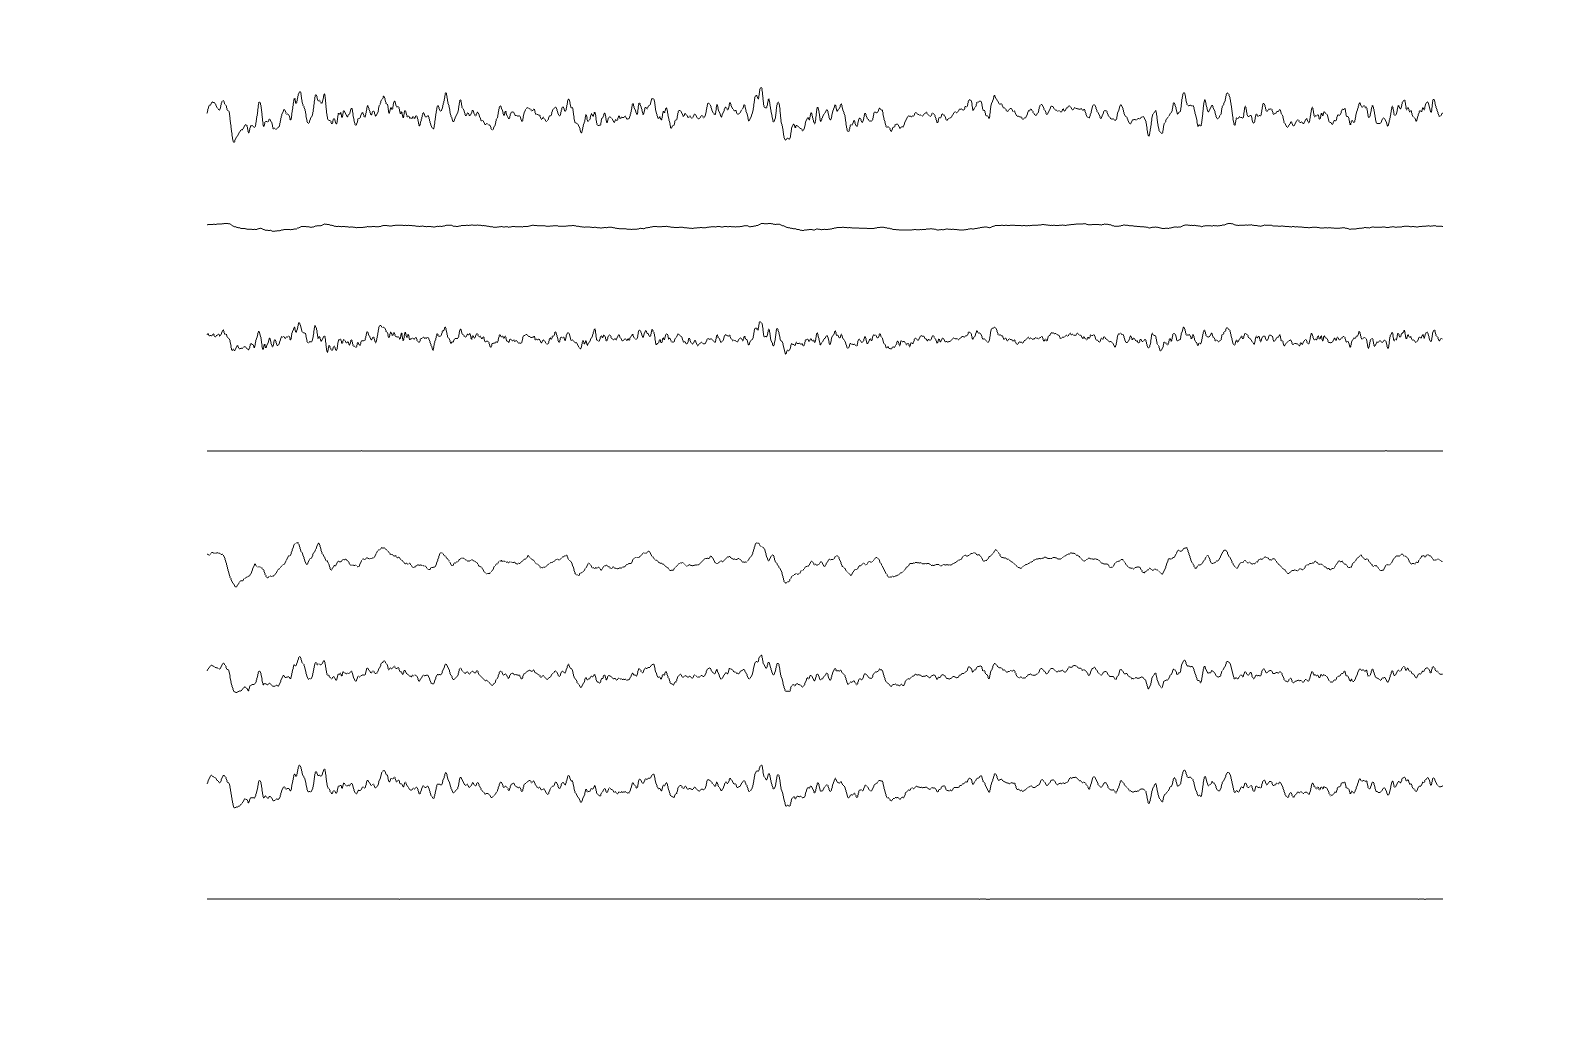

clf;  % Clears the current figure (Do not delete this line of code.)
figure;
strl = repmat({'E_'}, 1, number_of_channel);
chl = num2cell(1:number_of_channel);
save_as_TIF(strl, chl, 'total_img', 1, save_directory);

## 2 Signal Analysis Methology (STFT, CORR, etc)

### 2.1 Correlation of signals - Windowed Pearson Correlation Method

In order the to check if the signals are synchronized or not, it is necessary to initially select which channel values to compare.

Computed correlation of Ch1 vs Ch1: mean = 1, std = 9.42439e-16
Computed correlation of Ch1 vs Ch3: mean = 0.784888, std = 0.162941
Computed correlation of Ch1 vs Ch5: mean = 0.623777, std = 0.244163
Computed correlation of Ch1 vs Ch6: mean = 0.925972, std = 0.0860373
Computed correlation of Ch1 vs Ch7: mean = 0.940235, std = 0.0720796
Computed correlation of Ch3 vs Ch3: mean = 1, std = 9.22047e-16
Computed correlation of Ch3 vs Ch5: mean = 0.526576, std = 0.292028
Computed correlation of Ch3 vs Ch6: mean = 0.762469, std = 0.174611
Computed correlation of Ch3 vs Ch7: mean = 0.750245, std = 0.171363
Computed correlation of Ch5 vs Ch5: mean = 1, std = 9.37089e-16
Computed correlation of Ch5 vs Ch6: mean = 0.639098, std = 0.240257
Computed correlation of Ch5 vs Ch7: mean = 0.648528, std = 0.237152
Computed correlation of Ch6 vs Ch6: mean = 1, std = 9.39379e-16
Computed correlation of Ch6 vs Ch7: mean = 0.96684, std = 0.0410039
Computed correlation of Ch7 vs Ch7: mean = 1, std = 9.34592e-1

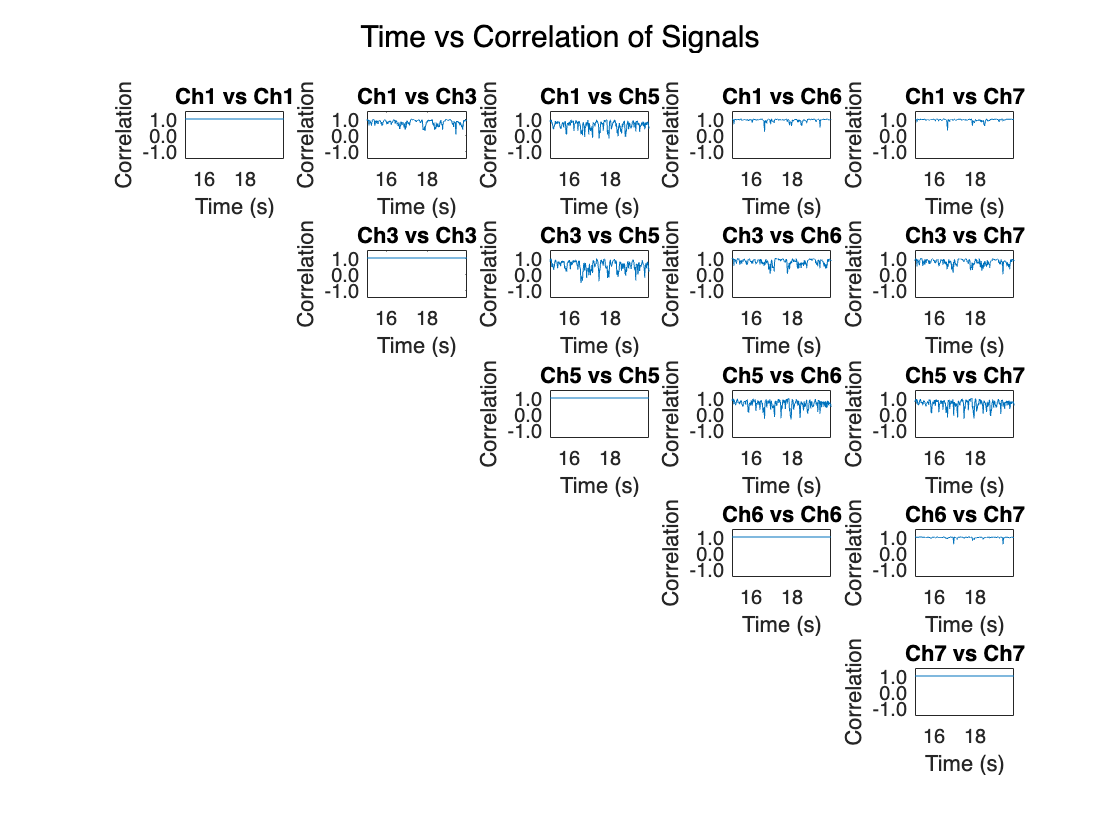

channel_list = [1,3,5,6,7];
mthd = signal_synchrometery();
mthd.simple_comparison(channel_list, save_directory, sampling_frequency, 15, 20);

### 2.2 Correlation of signals - Fullscale Pearson Correlation Method

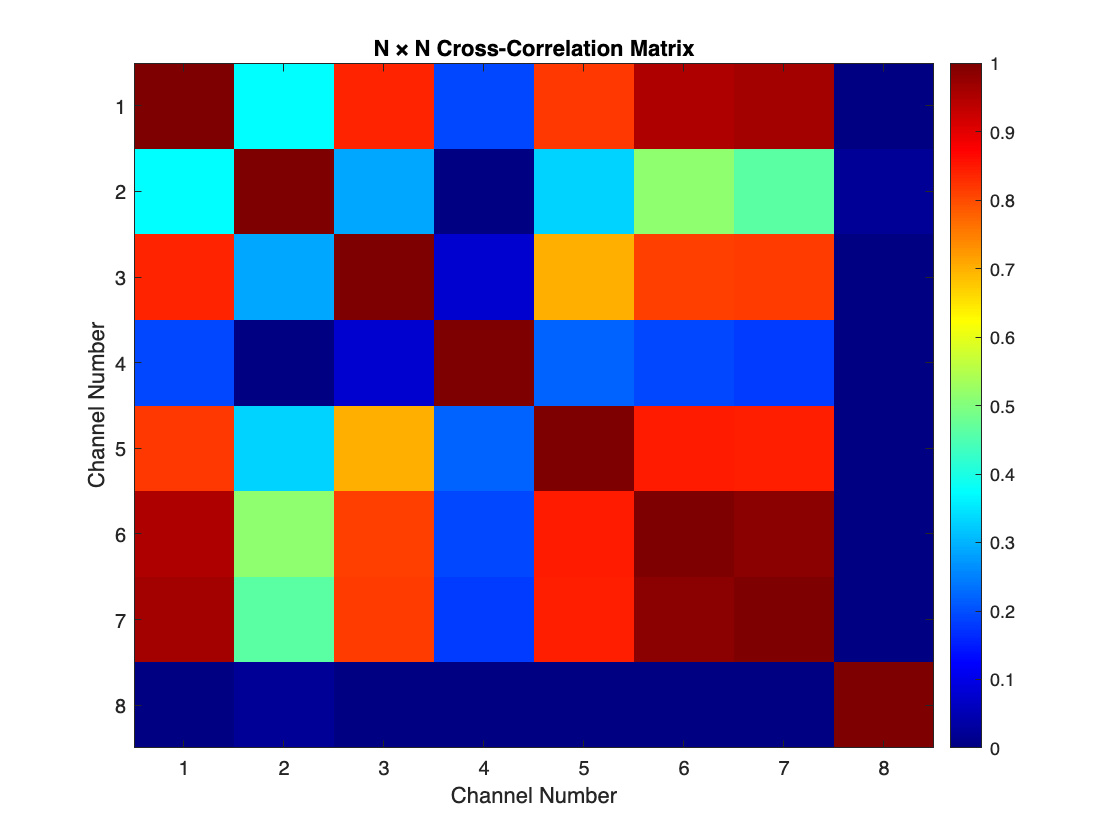

channel_list = [1,2,3,4,5,6,7,8];
mthd = signal_synchrometery();
mthd.correlation_matrix(channel_list, save_directory, sampling_frequency, 15, 20);